Question 1

Point-by-point sequence of steps for Steepest Descent:

- Start with an initial guess (x0, y0).

- Calculate the gradient of the function at the current point.

- Choose a suitable step size (also known as the learning rate or alpha).

- Update the current point using the formula

%x_old = something;
%y_old = something;
%alpha = something;
%x_new = x_old - alpha * gradient_of_f_with_respect_to_x
%y_new = y_old - alpha * gradient_of_f_with_respect_to_y

Repeat until gradient close to zero or a maximum number of iterations reached

Question 2

% Function to minimize: f(x, y) = (x - 4)^2 + (y - 3)^2
x = 1;
y = 1;
alpha = 3;

for i = 1:4
    gradient_x = 2 * (x - 4);
    gradient_y = 2 * (y - 3);
    x = x - alpha * gradient_x;
    y = y - alpha * gradient_y;
end

fprintf('Minimum point (x, y): (%.2f, %.2f)\n', x, y);

Minimum point (x, y): (-1871.00, -1247.00)


Question 3

% a.
h = 0.2;
t_values_a = 0:h:1;
y_values_a = zeros(size(t_values_a));
y_values_a(1) = 2; % Initial condition

for i = 2:length(t_values_a)
    y_values_a(i) = y_values_a(i-1) + h * y_values_a(i-1);
end

% b.
h = 0.1;
t_values_b = 0:h:1;
y_values_b = zeros(size(t_values_b));
y_values_b(1) = 2; % Initial condition

for i = 2:length(t_values_b)
    y_values_b(i) = y_values_b(i-1) + h * y_values_b(i-1);
end

% c.
exact_solution = 2 * exp(t_values_a);
error_a = abs(exact_solution - y_values_a(end));
error_b = abs(exact_solution(1:2:end) - y_values_b(end));

fprintf('Error for h = 0.2: %.6f\n', error_a(end));

Error for h = 0.2: 0.459924


fprintf('Error for h = 0.1: %.6f\n', error_b(end));

Error for h = 0.1: 0.736403



% d.
f = @(t, y) y;

% For h = 0.1
[t_values_heun_0_1, y_values_heun_0_1] = heun(f, [0, 1], 2, 0.1);

% For h = 0.2
[t_values_heun_0_2, y_values_heun_0_2] = heun(f, [0, 1], 2, 0.2);

Question 4

[t_ode45, y_ode45] = ode45(@(t,y) y, [0, 1], 2);

Bonus

f_bonus = @(t, y) y^2;

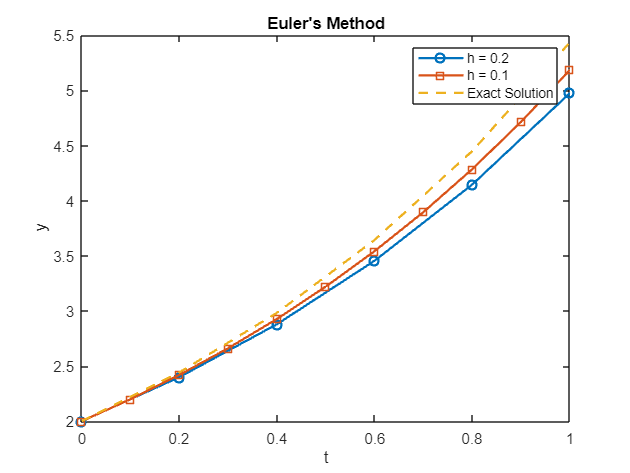

[t_bonus, y_bonus] = ode45(f_bonus, [0, 1], 2);
exact_solution_bonus = 2 ./ (1 - 2 * t_bonus);

% Calculate the error at t = 1
error_bonus = abs(exact_solution_bonus(end) - y_bonus(end));

fprintf('Error at t = 1 for dy/dt = y^2: %.6f\n', error_bonus);


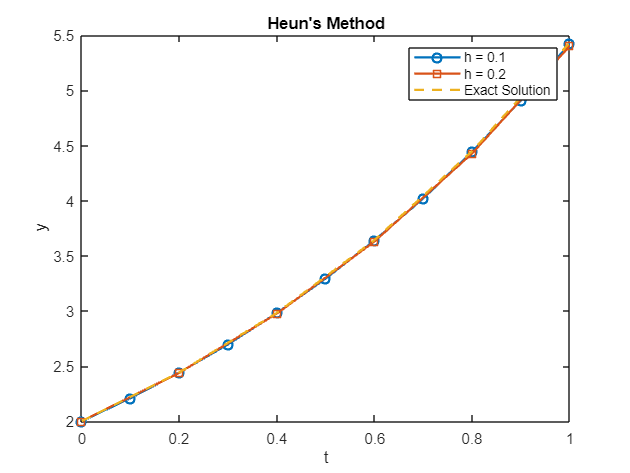


figure;

plot(t_values_a, y_values_a, '-o', t_values_b, y_values_b, '-s', t_values_a, exact_solution, '--', 'LineWidth', 1.5);
title('Euler''s Method');
xlabel('t');

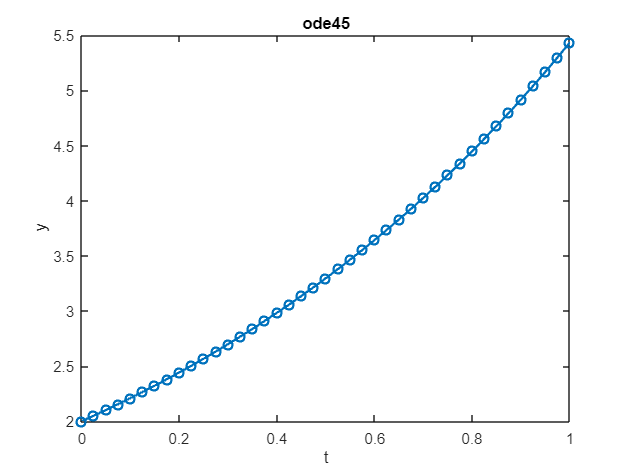

ylabel('y');
legend('h = 0.2', 'h = 0.1', 'Exact Solution');

plot(t_values_heun_0_1, y_values_heun_0_1, '-o', t_values_heun_0_2, y_values_heun_0_2, '-s', t_values_a, exact_solution, '--', 'LineWidth', 1.5);
title('Heun''s Method');
xlabel('t');

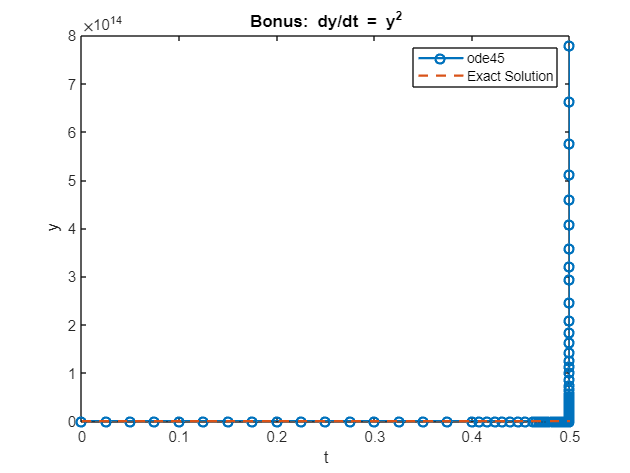

ylabel('y');
legend('h = 0.1', 'h = 0.2', 'Exact Solution');


plot(t_ode45, y_ode45, '-o', 'LineWidth', 1.5);
title('ode45');

xlabel('t');
ylabel('y');

plot(t_bonus, y_bonus, '-o', t_bonus, exact_solution_bonus, '--', 'LineWidth', 1.5);
title('Bonus: dy/dt = y^2');
xlabel('t');
ylabel('y');
legend('ode45', 'Exact Solution');

function [t, y] = heun(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    y = zeros(size(t));
    y(1) = y0;
    for i = 2:length(t)
        k1 = f(t(i-1), y(i-1));
        k2 = f(t(i-1) + h, y(i-1) + h * k1);
        y(i) = y(i-1) + (h / 2) * (k1 + k2);
    end
end